### Circuito Linea de Tranmision

clear all
Start_Freq=0.1E9;
End_Freq=2E9;
Step=500;
Z0=50;

netlist_TLfile='NetlistSpice\1_Circuito_Extra_ABCD.net';
netlistCell=Netlist2CellArray(netlist_TLfile)

netlistCell = 12×7 cell array
    {'R1'  }    {'N003'}    {'N006'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'R2'  }    {'N005'}    {'N007'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'C2'  }    {'N003'}    {'N010'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C1'  }    {'N009'}    {'N003'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C3'  }    {'N010'}    {'N005'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C4'  }    {'N005'}    {'N002'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'R5'  }    {'N003'}    {'N008'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'TL1' }    {'N006'}    {'0'   }    {'TL' }    {[        45]}    {[45]}    {[1.0000e+09]}
    {'R3'  }    {'N004'}    {'N005'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'R6'  }    {'N009'}    {'N001'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'SOC1'}    {'N008'}    {'


% Metodo Objeto Circuito Matlab
freq=linspace(Start_Freq, End_Freq, Step);
SMatlab4=SParametersFromNetlist(netlistCell,Start_Freq,End_Freq,Step,Z0);

TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [6 0 0 0]
            ParentPath: 'unnamed'


Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen'
                    Z0: 13
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [8 4 0 0]
            ParentPath: 'unnamed'


Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubCorto'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Short'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


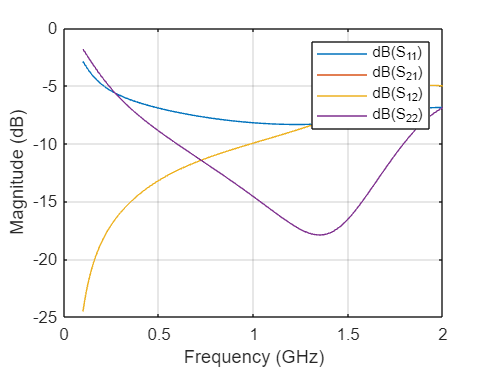


% ZMatlab=s2z(SMatlab4.Parameters,50);
% ZMatlab=zparameters(ZMatlab,freq);
% param = rfparam(ZMatlab,1,1);
% plot(freq,real(param));

rfplot(SMatlab4);




% Metodo circuito equivalente
nuevo_Netlist=NetlistCircuitoEquivalente(netlistCell)

newType = 'SSC'

nuevo_Netlist = 12×7 cell array
    {'R1'  }    {'N003'}    {'N006'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'R2'  }    {'N005'}    {'N007'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'C2'  }    {'N003'}    {'N010'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C1'  }    {'N009'}    {'N003'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C3'  }    {'N010'}    {'N005'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'C4'  }    {'N005'}    {'N002'}    {'C'  }    {[1.2000e-11]}    {[ 0]}    {[         0]}
    {'R5'  }    {'N003'}    {'N008'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'SSC' }    {'N006'}    {'0'   }    {'SSC'}    {[        45]}    {[45]}    {[1.0000e+09]}
    {'R3'  }    {'N004'}    {'N005'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'R6'  }    {'N009'}    {'N001'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}
    {'SOC1'}    {'N008'}    

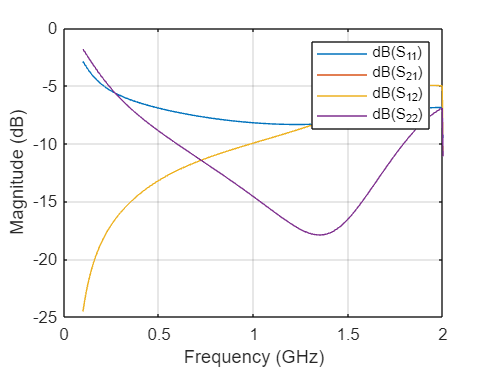

% Matriz_Z=Z_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);
% Matriz_S=z2s(Matriz_Z,50);

Matriz_Y=Y_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);
Matriz_S=y2s(Matriz_Y,Z0);


freq=linspace(Start_Freq, End_Freq, Step);
SParamsObject=sparameters(Matriz_S,freq,50);
rfplot(SParamsObject)


% ----- INICIO----------


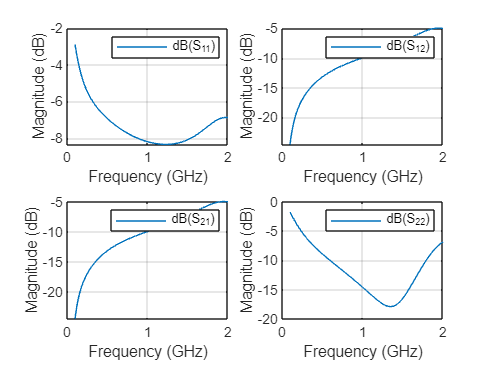

subplot(2,2,1)
rfplot(SMatlab4,1,1)
subplot(2,2,2)
rfplot(SMatlab4,1,2)
subplot(2,2,3)
rfplot(SMatlab4,2,1)
subplot(2,2,4)
rfplot(SMatlab4,2,2)



% subplot(2,2,1)
% smithplot(SMatlab4,1,1)
% subplot(2,2,2)
% smithplot(SMatlab4,1,2)
% subplot(2,2,3)
% smithplot(SMatlab4,2,1)
% subplot(2,2,4)
% smithplot(SMatlab4,2,2)
% 
% subplot(2,2,1)
% rfplot(SMatlab4,1,1,'angle')
% subplot(2,2,2)
% rfplot(SMatlab4,1,2,'angle')
% subplot(2,2,3)
% rfplot(SMatlab4,2,1,'angle')
% subplot(2,2,4)
% rfplot(SMatlab4,2,2,'angle')

% subplot(2,2,1)
% param = rfparam(ZMatlab,1,1);
% plot(freq,real(param));
% subplot(2,2,2)
% param = rfparam(ZMatlab,1,2);
% plot(freq,real(param));
% subplot(2,2,3)
% param = rfparam(ZMatlab,2,1);
% plot(freq,real(param));
% subplot(2,2,4)
% param = rfparam(ZMatlab,2,2);
% plot(freq,real(param));
